# Lecture 10 Interferometric Imaging

## 1. Continuous wave interferometry

### 1.1 Michelson interferometry setup

A coherent monochromatic wave can be used to measure distance using an interferometer based on measuring the time delay. One of the most common setups in free-space for imaging purposes is the Michelson interferometer, shown in ILL. 1.1.

In a Michelson interfereomer setup, the beam from a coherent source is divided into the sample arm (to the object), and the reference arm (to the mirror) by a beam splitter. The beams are reflected from both paths and recombined by the same beam splitter. The interference of the reflected beam from the sample arm and the reference arm is measured on the photodetector.

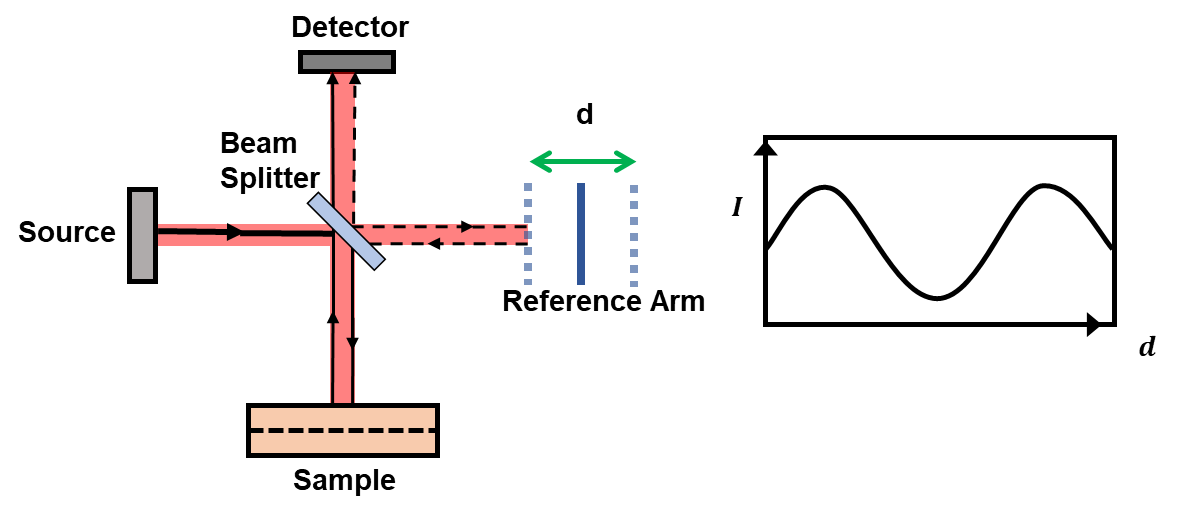

**ILL. 1.1*** Michelson interferometer *

When a wave travels a distance $d_o$, it undergoes a phase shift $\phi =kd_o =2\pi \frac{d_o }{\lambda }$, where $\lambda$ is the wavelength.

Time delay $\tau_o$ in the sample arm introduces a phase shift $\phi =\omega \tau_o$, where $\omega$ is the angular frequency. The time delay is associated with the distance $d_o$. $\tau_o =\frac{d_o }{c}$,


$$\phi =\omega \tau_o =\omega \frac{d_o }{c}=2\pi \frac{d_o }{\lambda }$$


The distance and time delay can therefore be estimated by measuring the phase. A interferometer calculates the phase shift difference of the reference arm and sample arm by measuring the intensity of the interference.

### 1.2 Interferometry with swept reference arm

The intensity of the superposition of two coherent harmonic waves of intensities $I_1$ and $I_2$ with a phase difference $\phi$ is:


$$I=I_1 +I_2 +2\sqrt{I_1 I_2 }\cos \phi$$


If $r=\frac{E_2 }{E_1 }$ is the ratio of the electric fields, then $\phi =\arg \left(r\right)$ and $\frac{I_2 }{I_1 }={\left|r\right|}^2$.


$$I\propto1+{\left|r\right|}^2 +2\left|r\right|\cos \phi$$


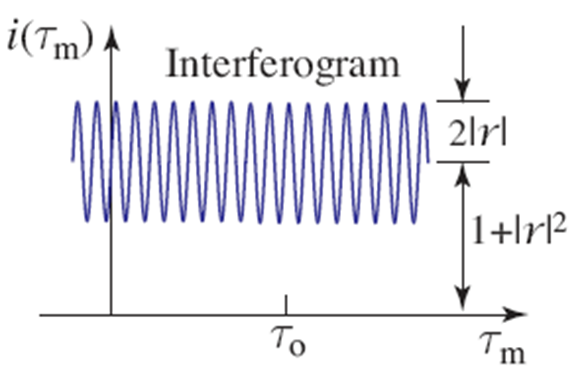

**ILL. 1.2*** Interferogram from Michelson interferometer with CW laser and swept reference arm *

Now, if we move the reference arm, essentially change the time delay, the photocurrent $i\left(\tau_m \right)$, which is propotional to the intensity of the interference, is also a function of the reference arm delay. Specifically,


$$i\left(\tau_m \right)\propto1+{\left|r\right|}^2 +2\left|r\right|\cos \left\lbrack \omega \left(\tau_m -\tau_o \right)+\phi_r \right\rbrack ,$$


where $\tau_0$ and $\tau_m$ are time delay of the object and the reference mirror, respectively. The interefrogram is a periodic function of the delay time difference $\tau =\tau_m -\tau_o$. Since the interferogram is recorded by moving the mirror, it is often expressed in terms of distances $d_r =c\tau_m$, $d_o =c\tau_o$, and the difference $d=d_r -d_o =c\tau$. 

The fringes of the inteferogram have a contrast (ratio of the amplitude of the sinusoidal component to the background) equal to $\frac{2\left|r\right|}{\left(1+{\left|r\right|}^2 \right)}$. This may be used to determine the reflectance $\mathrm{R}={\left|r\right|}^2$ of the object. If $r$ is known to be real, i.e., the reflecion does not introduce a phase shift, $\phi_r =0$, then the depth of the object $d_o$ may be estimated by finding a $d_r$ that provides the maximum signl. Because the interferogram reaches a maximum value when $\tau =0$, i.e., when $\tau_0 =\tau_m$ or $d_o =d_r$. However, since there are many maxima separated by the period $T=\frac{2\pi }{\omega }$, which corresponds to a distance $d=c\left(\frac{2\pi }{\omega }\right)=\lambda$, there are ambiguities in depth estimation. Specifically, adding or substractin a distance equal to integer multiples of the wavelength, you will have the same interference signal. This poses a major difficulty for uniquely determining the depth, known as the phase wrapping problem.

***Example 1.1 ***

Interferogram from CW laser

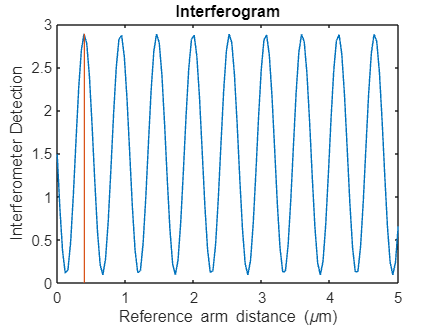

%% michelson interferometer for single surface CW wave
lambda0 = 0.532; % wavelength unit um
z_step = lambda0/4;
z=0.399; % the distance of object arm [Unit: um]
r=0.7;% relative reflectivity
phi_r = 0; % the phase of the reflector

% swept reference arm distance between 0 and 5 um
d = linspace(0,5,128); % the distance, unit um
% interferogram

intf = 1+r.^2+2*r.*cos(2*pi./lambda0.*(z-d)+phi_r);

figure;
plot(d,intf,[z,z],[0,1+r^2+2*r]);
set(gcf,'Position', [100 100 400 300])
title('Interferogram')
xlabel('Reference arm distance (\mum)')
ylabel('Interferometer Detection')

#### **1.2.1 Depth topography**

When the range (depth or elevation) of the surface of the object is position dependent, i.e., $d_o =d_o \left(x,y\right)$, the measured intensity at a fixed position of the mirror (fixed $d_r$) of the image is determined by substituting $\tau =\frac{d}{c}$ and $\omega =\frac{2\pi c}{\lambda }$,


$$i\left(x,y\right)\propto1+{\left|r\right|}^2 +2\left|r\right|\cos \left\lbrack 2\pi \frac{d_r -d_o \left(x,y\right)}{\lambda }+\phi_r \right\rbrack$$


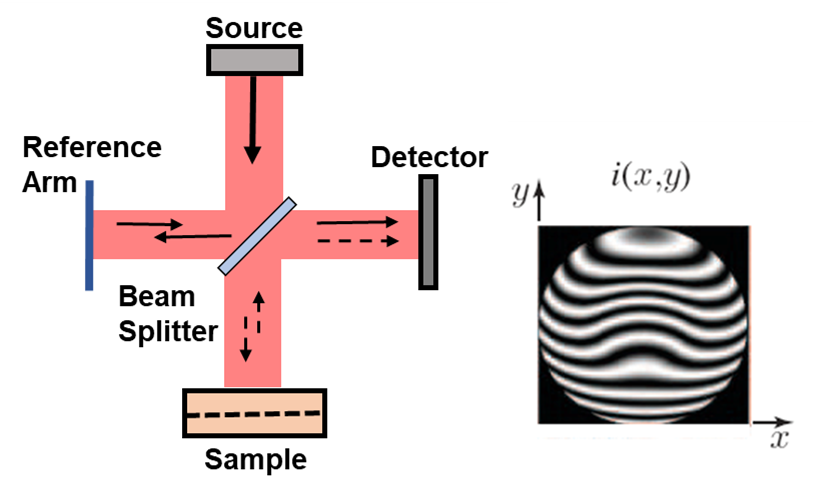

**ILL. 1.3 ***Interferogram *$I\left(x,y\right)$* recorded by a camera in with Michelson interferometer setup to image the topography of a surface of depth *$d_o \left(x,y\right)$*.*

### 1.3 Limitations of single wavelength CW interferometry for axial imaging

Axial imaging takes the reflected signal (the back scattering from all scattering layers) and interfer it with the reference beam. The goal is to identify the scatterer location and reflectivity $R\left(y,z\right)$ from the interferogram. The imaging along y direction is achieved through lateral scanning of the beam.

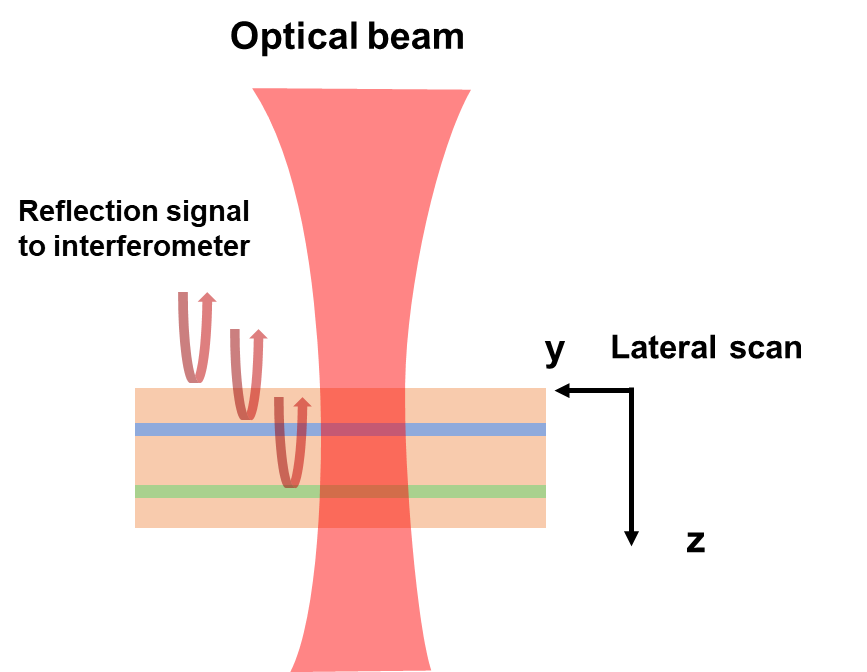

**ILL. 1.4 ***Axial imaging using an interferometer*

***Example 1.2 ***

Interferogram for axial imaging

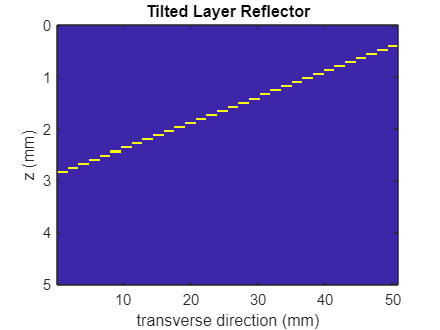

% interferometer for multiple scenarios, please use the pull down menu to select
z=linspace(0,5,128); % the distance, unit mm
y=linspace(1,50,32); % transverse direction, unit mm
[Y,Z]=ndgrid(y,z);
R=zeros(length(y),length(z));% relative reflectivity matrix

layer = "Tilted Layer Reflector";

if strcmp(layer,'Single Layer Reflector')
    R(Z==z(50))=0.2;
elseif strcmp(layer,'Tilted Layer Reflector')
    R(ceil(20*Z-Y-20*z(10))==0)=0.2;
elseif strcmp(layer,'Concave Layer Reflector')
     radi=600;
     R(round( (radi*(Z-z(100))+( Y-y(end/2) ).^2)/radi*10 )==0)=1;
     R_c=repmat(sum(R,2),[1,length(z)]); % normalization factor
     R=R./R_c*.1;
elseif strcmp(layer,'Double Layer Reflector')
    R(Z==z(30))=0.2;
    R(Z==z(50))=0.1;
end
R_90 = rot90(R,3);
figure;
imagesc(y,z,R_90)
set(gcf,'Position', [100 100 400 300])
title(layer)
xlabel('transverse direction (mm)')
ylabel('z (mm)')

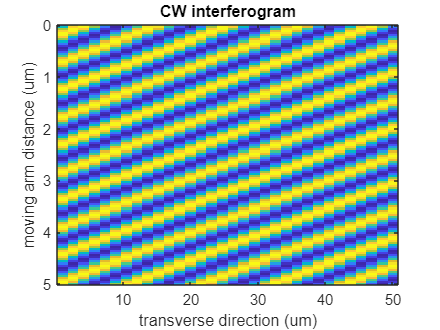

% single wavelength generated interferogram
lambda0 = 0.532; % unit um
% swept arm distance 
d = linspace(0,5,128); % the distance, unit um
% interferogram
Ing = zeros(length(y),length(d));

for ii=1:length(d)
    Ing(:,ii) = 1+sum(R.^2+2.*R.*cos(2*pi./lambda0.*(Z-d(ii))),2);
end
Ing_90 = rot90(Ing,3);
figure;
imagesc(y,d,Ing_90);
set(gcf,'Position', [100 100 400 300])
title('CW interferogram')
ylabel('moving arm distance (um)')
xlabel('transverse direction (um)')

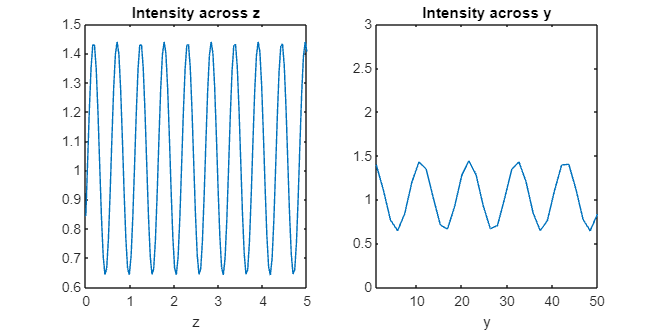

figure;
set(gcf,'Position', [100 100 600 300])
subplot(121) %Intensity across z slice
plot(d,Ing(5,:));
title('Intensity across z')
xlabel('z')
xlim([0,5]);
subplot(122)%Intensity across y slice
plot(y,Ing(:,10)); axis([y(1),y(end),0,3])
title('Intensity across y')
xlabel('y')

**Can the CW interferogram be used for depth imaging?**

While the interferogram in ILL. 1.3 provides some informaiton on the reflectance and the distance $d_o =c\tau_o$ to a single reflector, it cannot be used to simultaneously locate multiple reflectors at different depths within an object, i.e., it cannot be used for axial imaging (estimation of the reflectance $r$ as a function of the depth $z$). For example, if we consider an object with two reflecting layers with reflectance of $r_1$ and $r_2$ at depths $d_1$ and $d_2$, corresponding to time delays of $\tau_1$ and $\tau_2$. The interferogram is

$i\left(\tau_m \right)\propto1+R_b +2\left|r_1 \right|\cos \left\lbrack \omega \left(\tau_m -\tau_1 \right)+\phi_1 \right\rbrack +2\left|r_2 \right|\cos \left\lbrack \omega \left(\tau_m -\tau_2 \right)+\phi_2 \right\rbrack$,

has two sinusoidal terms of the same angular frequency $\omega$ but different amplitudes and phases ($1+R_b$ is a constant bias, and $\phi_1$ and $\phi_2$ are the phases associated with $r_1$ and $r_2$). Since the sum of two sinusoidal terms is equal to a single sinusoidal function of $\tau_m$ with frequency $\omega$ and an amplitide and a phase related to the amplitudes and phases of the two components, it is not possible to separate the two amplitudes and two phases (four unknowns and two equations) to provide estimates for the reflectance and depths of the two reflectors. This can be visualized in *Example 1.2* above, when 'Double Layer Reflector' is selected.

## 2. Interferometry with a swept frequency CW source

In swept frequency Michelson interferometer, the reference arm is fixed; instead, the source wavelength is scanned. For multiple reflectors indexed by $l$, the wavelength-dependent interferogram is:


$$i\left(\tau_m ,\omega \right)\propto1+{\mathrm{R}}_b +\sum_l 2\left|r_l \right|\cos \left\lbrack \omega \left(\tau_m -\tau_l \right)+\phi_l \right\rbrack$$


The measurement $i\left(\tau_m ,\omega \right)$ at a set of source frequencies, $\omega$, encodes the depth-dependent information through the phase term $\omega \left(\tau_m -\tau_l \right)$. To find the reflectance and delay, we can calculate the inverse Fourier transform to decode $\left|r_l \right|$ and $\tau_l$.

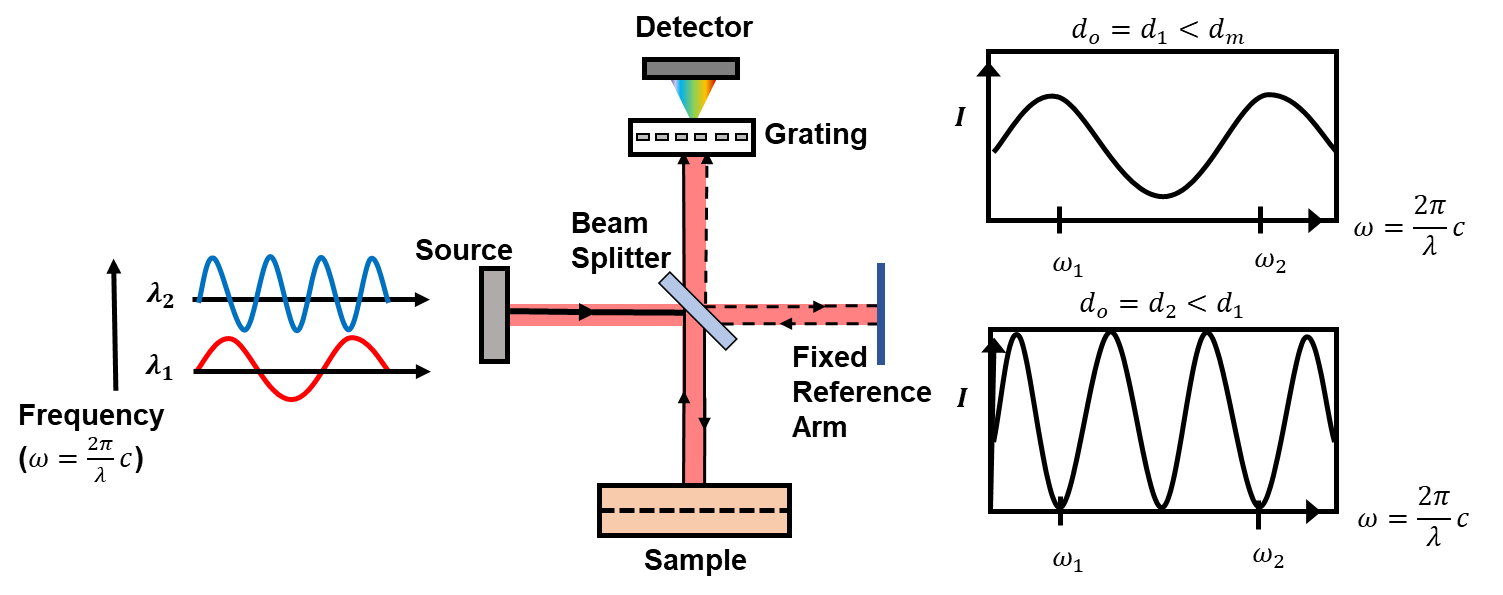

**ILL. 2.1 ***Interferometry with a swept frequency CW source*

***Example 2.1 ***

Interferometry with a swept frequency CW source

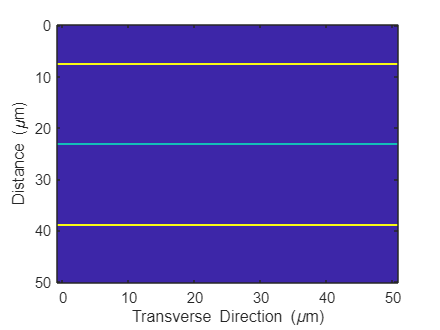

%% interferometer for single surface
lamda0 = 0.7; % starting wavelenght[unit: um]
lamda1 = 1.3; % end wavelenght[unit: um]
k= 2*pi*linspace(1/lamda0,1/lamda1,128); % sweeping wavelength 
% (k is wave number unit um^-1)
z=linspace(0,50,128); % the distance, unit um
y=linspace(0,50,32); % transverse direction, unit um
[Y,Z]=ndgrid(y,z);
R=zeros(length(y),length(z));% relative reflectivity matrix

layer = "Multiple Layer Reflector";
if strcmp(layer,'Single Layer Reflector')
    R(Z==z(20))=0.2;
elseif strcmp(layer,'Multiple Layer Reflector')
    R(Z==z(20))=0.2;
    R(Z==z(60))=0.1;
    R(Z==z(100))=0.2;
end
R_90 = rot90(R,3);
figure()
imagesc(z,y,R_90)
set(gcf,'Position', [100 100 400 300])
ylabel("Distance (\mum)")
xlabel("Transverse Direction (\mum)")

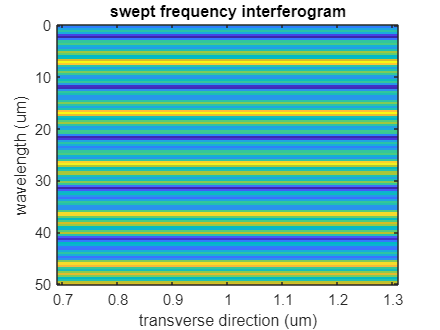

%% swept frequency interferogram
% reference arm distance 
d = 0; % the distance of one arm, unit um
% interferogram
Ing = zeros(length(y),length(k));

for ii=1:length(k)
    Ing(:,ii) = 1+sum(R.^2+2*R.*cos(k(ii).*(Z-d)),2);
end
Ing_90 = rot90(Ing,3);
figure;
set(gcf,'Position', [100 100 400 300])
imagesc(2*pi./k,y,Ing_90);
title('swept frequency interferogram')
ylabel('wavelength (um)')
xlabel('transverse direction (um)')

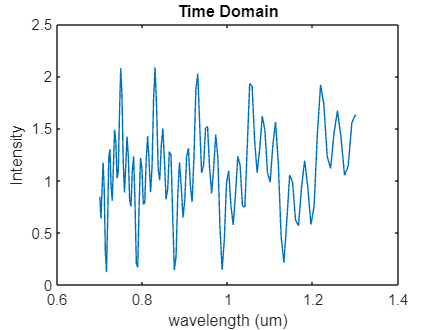

figure;
set(gcf,'Position', [100 100 400 300])
plot(2*pi./k,Ing(5,:));
%plot(k,Ing(5,:));
title('Time Domain')
xlabel('wavelength (um)')
ylabel('Intensity')

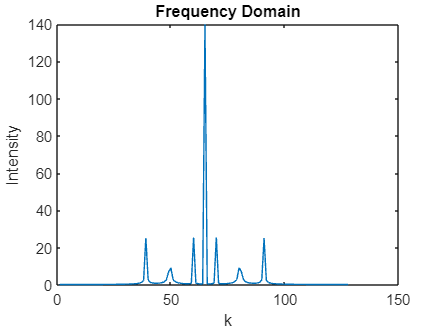

%% frequency domain OCT
a=fftshift(fft(Ing(5,:)));
figure;
set(gcf,'Position', [100 100 400 300])
plot(abs(a))
title('Frequency Domain')
xlabel('k')
ylabel('Intensity')

By sweeping the frequency, the interferogram is a function of $\omega$, instead of $\tau$ (or $d$). *Example 2.1* shows a similar type of 2D object. The depth information $\left(z\right)$ is encoded in frequency, and its inverse Fourier transform shows the reflectors' locations and reflectances.

## 3. Interferometry with low coherent source

### 3.1 Interferometry with pulsed wave

An ultrashort pulse may be directly used for axial imaging using time of flight (ToF) measurements. The detector must be sufficiently fast to determine the time of arrival with high resolution, as shown in the previous lecture. Here, instead of using a fast detector, we use an interferometric setup to interfere the reflected pulse with a reference pulse. The delay can also be determined from the interferogram using a slow detector. 

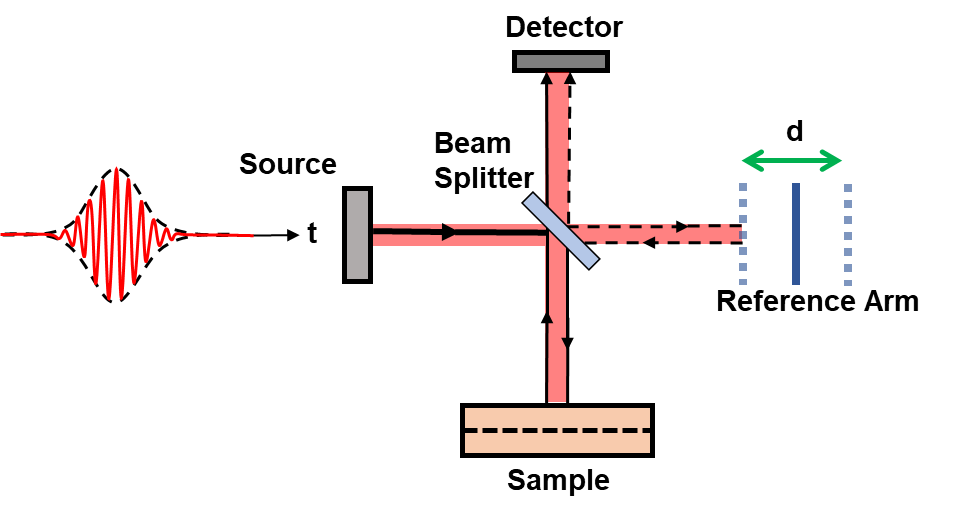

**ILL. 3.1*** Interferometry with pulsed light*

Let the field profile of the pulse be $U\left(t\right)$. The total intensity acquired on the detector, containing the reference pulse interfere with the sample pulse, is proportional to ${\left|U\left(t-\tau_m \right)+r\;U\left(t-\tau_o \right)\right|}^2$, where $r$ is he reflectivity of the sample arm. The detector's temoporal response is slow compared with the pulse width, it simply measures the temporal integral of the intensity. This is the same as integrating the function ${\left|U\left(t\right)+\mathrm{r}\;U\left(t+\tau \right)\right|}^2$ over $t$, where $\tau =\tau_m -\tau_o$ is the time delay difference of reference and sample arms. Expand the expression of the intensity,

 
$${\left|U\left(t\right)+U\left(t+\tau \right)\right|}^2 ={\left|U\left(t\right)\right|}^2 +{\left|r\right|}^2 {\left|U\left(t+\tau \right)\right|}^2 +rU^* \left(t\right)\;U\left(t+\tau \right)+r^* U\left(t\right)U^* \left(t+\tau \right)$$


leads to the following expression for the measured signal:


$$i\left(\tau \right)=\left(1+{\left|r\right|}^2 \right)G\left(0\right)+2\textrm{Re}\left\lbrace \textrm{rG}\left(\tau \right)\right\rbrace =G\left(0\right)\;\left\lbrack 1+{\left|r\right|}^2 +\textrm{Re}\left\lbrace \textrm{rg}\left(\tau \right)\right\rbrace \right\rbrack$$


where


$$G\left(\tau \right)=\int_{-\infty }^{\infty } U^* \left(t\right)\;U\left(t+\tau \right)\;\textrm{dt}$$


is the autocorrelation function of the pulse, $G\left(0\right)$ is the area under the pulse intensity, and $g\left(\tau \right)=G\left(\tau \right)/G\left(0\right)$, is the normalized autocorrelation function. For a pulse with carrier freqeuncy of $\omega_0$, and a pulse envolope with modulation $A\left(t\right)$, the field profile is


$$U\left(t\right)=A\left(t\right)\exp \left(j\omega_0 t\right)$$


The autocorrelation function is:


$$G\left(\tau \right)=G_A \left(\tau \right)\exp \left(j\omega_0 \tau \right)$$


$G_A \left(\tau \right)$ is the autocorrelation function of the pulse envolope. The normalized autocorrelation function is 


$$g\left(\tau \right)=\left|g_A \left(\tau \right)\right|\exp \left\lbrack j\left(\omega_0 \tau \right)+\phi_A \right\rbrack ,$$


where $\phi_A =\arg \left\lbrace G_A \left(\tau \right)\right\rbrace$

The interferogram of the pulsed wave is

$i\left(\tau_m \right)\propto1+{\left|r\right|}^2 +2\left|r\right|\left|g\left(\tau_m -\tau_0 \right)\right|\cos \left\lbrack \omega_0 \left(\tau_m -\tau_0 \right)+\phi \right\rbrack$, 

where $\phi =\phi_A +\arg \left\lbrace r\right\rbrace$.

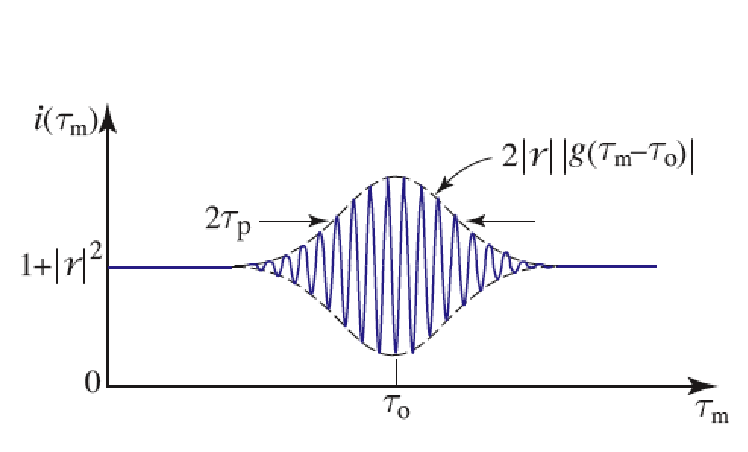

**ILL. 3.2 ***Interferogram of a pulsed wave*

The pulsed-wave interferogram extends over an interval roughly equal to twice the pulse's temporal width, which allows the head of the pulse from one arm to interfere with the tail of the pulse form the other arm.

***Example 3.1 ***

Pulsed-wave interferogram.

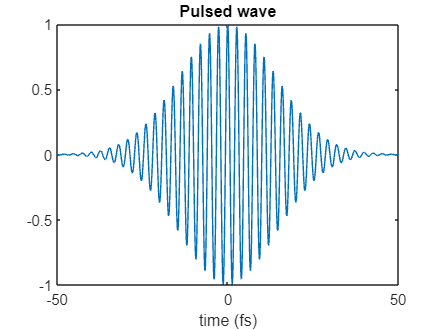

% a Gaussian shape pulse with width 10 fs. central wavelength 800 nm.
lambda0 = 0.8; %central wavelength [Unit: um]
c = 3e8; %speed of light [Unit: m/s}
omega0 = 2*pi*c/(lambda0*1e-6);

t = linspace(-50,50,1024); % unit fs
r = 0.5; %reflectivity
tau = 20; % Pulse width [Unit: fs]
a = exp(-t.^2./tau^2); % Pulse envelope

u = a.*exp(1i.*omega0.*t*1e-15);
g0 = sum(u.*conj(u));% Pulse energy
g_tau = conv(u,u,'same')/g0; % normalized

figure;
plot(t,real(u))
set(gcf,'Position', [100 100 400 300])
xlabel('time (fs)')
title('Pulsed wave')

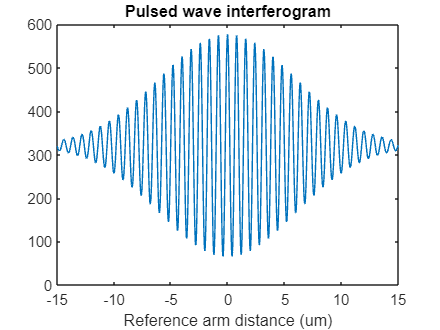

inf = g0*(1+r^2+2*real(r*g_tau)); % interferogram of the pulse

figure;
plot(3e8.*t.*1e-15*1e6,inf);
set(gcf,'Position', [100 100 400 300])
xlabel('Reference arm distance (um)')
title('Pulsed wave interferogram')

### 3.2 Optical Coherent Tomography (OCT)

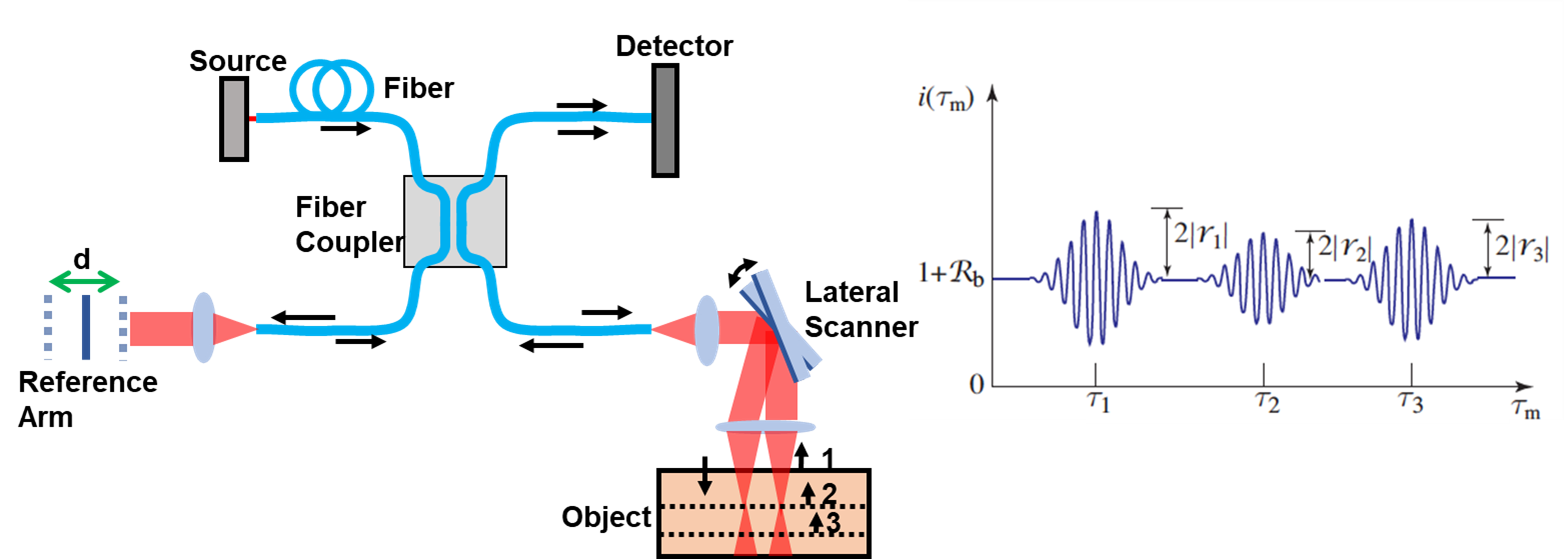

**ILL. 3.3 ***Time Domain Optical Coherent Tomography (TD-OCT) using low coherent source*

The pulsed wave contains multiple freqency components. The auto-correlation essentially measures the coherence of the light source. Therefore, the derivation above is not limited to a chirp-free pulse as in *Example 3.1*, it can also be extended to low coherence source. 


$$i\left(\tau_m \right)\propto1+{\left|r\right|}^2 +2\left|r\right|\left|g\left(\tau_m -\tau_0 \right)\right|\cos \left\lbrack \omega_0 \left(\tau_m -\tau_0 \right)+\phi \right\rbrack$$


Coherence function:

$G\left(\tau \right)=\left\langle U^* \left(t\right)U\left(t+\tau \right)\right\rangle$,

where $U\left(t\right)$is the amplitude of the field, which expand over a broad spectrum. The normalized coherence function:


$$g\left(\tau \right)=\frac{G\left(\tau \right)}{G\left(0\right)}$$


The width of the coherence function determines the depth resolution of the low-coherence interferometer. The system is more widely known as Optical Coherence Tomography (OCT). Generally speaking, OCTs can be categorized to time-domain (TD-OCT) and frequency domain (FD-OCT). TD-OCT uses low-coherence light source. Only when reference arm and sample arm difference is within the coherence length of the source, can one observe the interference; therefore by scanning the reference arm distance, we can use this coherence window to selectively image a certain depth within the sample. The FD-OCT uses the swept-source interfereometer setup, shown in ILL. 3.4. A spectrometer is placed on the detector side with a fixed-position reference arm.

#### **3.2.1 Comparison between TD-OCT and FD-OCT**

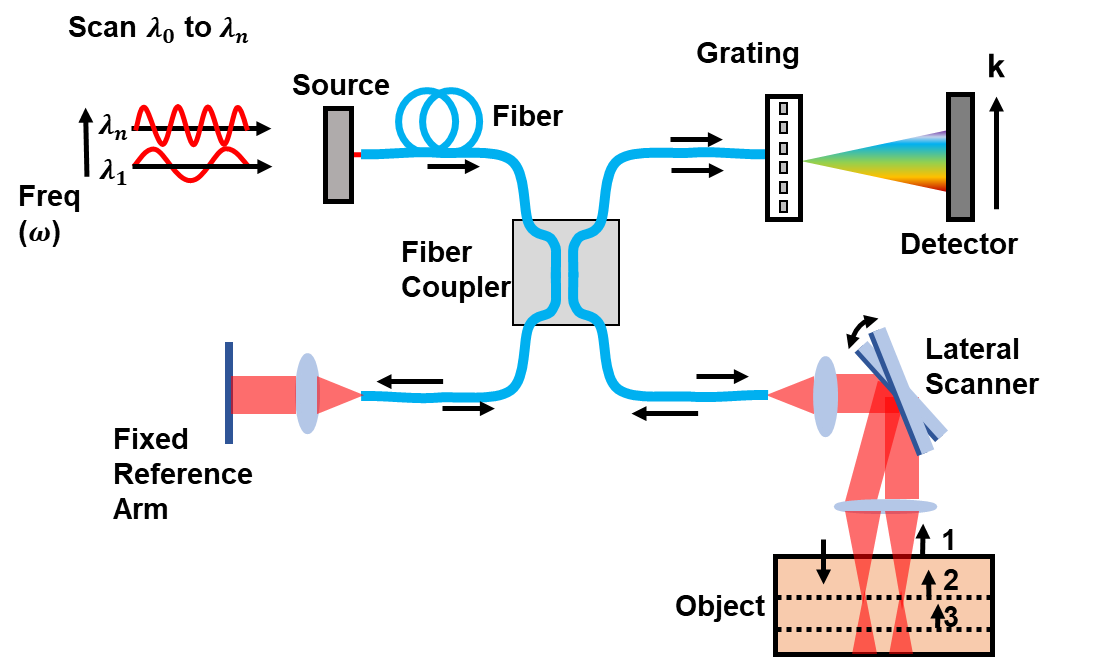

**ILL. 3.4 ***Frequency domain OCT (FD-OCT), with a source scanned from *$\lambda_0$* to *$\lambda_n$* and a fixed reference arm.*

**Sensitivity:** FD-OCT typically has a higher sensitivity compared to TD-OCT. This enables clearer images and better imaging of structures deeper within tissues.

**Moving Parts:** As mentioned above, TD-OCT relies on a mechanically moving reference mirror to obtain depth scans, which can be a source of wear and tear and reduce system longevity. FD-OCT doesn't need a moving reference arm, leading to increased system durability.

**Speed: **Due to the slow movement of the reference arm in TD-OCT, FD-OCT systems can aquire data significantly faster, making it more suatable for imaging areas that move.

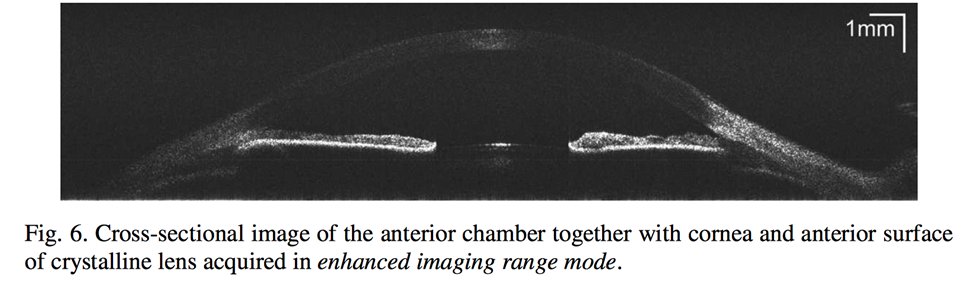

**ILL. 3.5 ***Anterior OCT of the cornea and lens, from Gora, Michalina, et al. "Ultra high-speed swept source OCT imaging of the anterior segment of human eye at 200 kHz with adjustable imaging range." Optics Express 17.17 (2009): 14880-14894.*